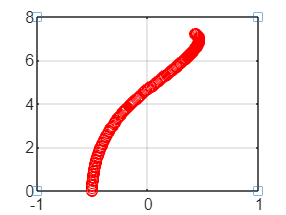

clear
clc
tspan = [0 10];
v0 = 1.9;
n = 250;
y0 = -0.5;

[y,vy,ty] = yEuler(@yOde,tspan,y0,n);
[x,vx,tx] = xEuler(@xOde,tspan,v0,n);
[d1,d2] = drawField();


[x1,vx1,y1,vy1] = calcStop(x,vx,y,vy,n+1);


% plot(y,x,'o b',d1,d2,'s',y1,x1,'x r')
plot(d1,d2,'s',y1,x1,'o r')
grid on
hold off

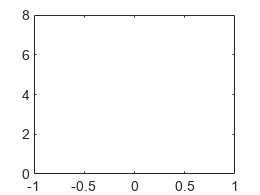

animation(x1,y1)